clear all
load("data\longitudinal_dimnsional_derivatives.mat")
load("data\longitudinal_data.mat","alfa_1")
load("data\enviroment_data.mat","v_sound")
load("data\flight_cases_data.mat","mach")
r= 1;
c=2;
g= 9.81;
theta_1 = alfa_1(r, c); 
Vp1 = v_sound(r,c)*mach(2);

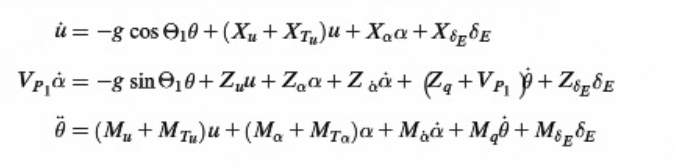

%Macierz A
Au = [(Xu(r,c)+Xtu(r,c)), Xalpha(r,c) 0 ,-g*cos(theta_1)];
Aalpha = [Zu(r,c), Zalpha(r,c) , (Zq(r,c)+Vp1), -g*sin(theta_1)]/(Vp1-Zalphadot(r,c));
Aq = [Mu(r,c)+Mtu(r,c)+Malphadot(r,c)*Aalpha(1),Malpha(r,c)+Mtalpha(r,c)+Malphadot(r,c)*Aalpha(2),Mq(r,c)+Malphadot(r,c)*Aalpha(3),Malphadot(r,c)*Aalpha(4)];
Atheta = [0,0,1,0];
A = [Au;Aalpha;Aq;Atheta]

A =    -0.1117   17.8323         0   -9.7858
   -0.0004    0.9223    0.9573   -0.0016
    0.0002   -2.4909   -1.0326    0.0005
         0         0    1.0000         0


%Macierz B
B= [XdeltaE(r,c);ZdeltaE(r,c)/(Vp1-Zalphadot(r,c));ZdeltaE(r,c)*Malphadot(r,c)/(Vp1-Zalphadot(r,c))+MdeltaE(r,c);0]

B =          0
   -0.0559
   -1.6758
         0


%Macierz C
C= [0,0,1,0]

C =      0     0     1     0


%Macierz D
D = zeros(1)

D = 0


st = {'u','alpha','q','theta'};
in = {'deltaE'};
out = {'q'};
M  = ss(A,B,C,D, 'inputname', in , 'statename', st , 'outputname', out)

M =
 
  A = 
                   u       alpha           q       theta
   u         -0.1117       17.83           0      -9.786
   alpha  -0.0003786      0.9223      0.9573   -0.001647
   q       0.0002252      -2.491      -1.033   0.0004594
   theta           0           0           1           0
 
  B = 
            deltaE
   u             0
   alpha  -0.05585
   q        -1.676
   theta         0
 
  C = 
          u  alpha      q  theta
   q      0      0      1      0
 
  D = 
      deltaE
   q       0
 
Continuous-time state-space model.



% % impulse(M)